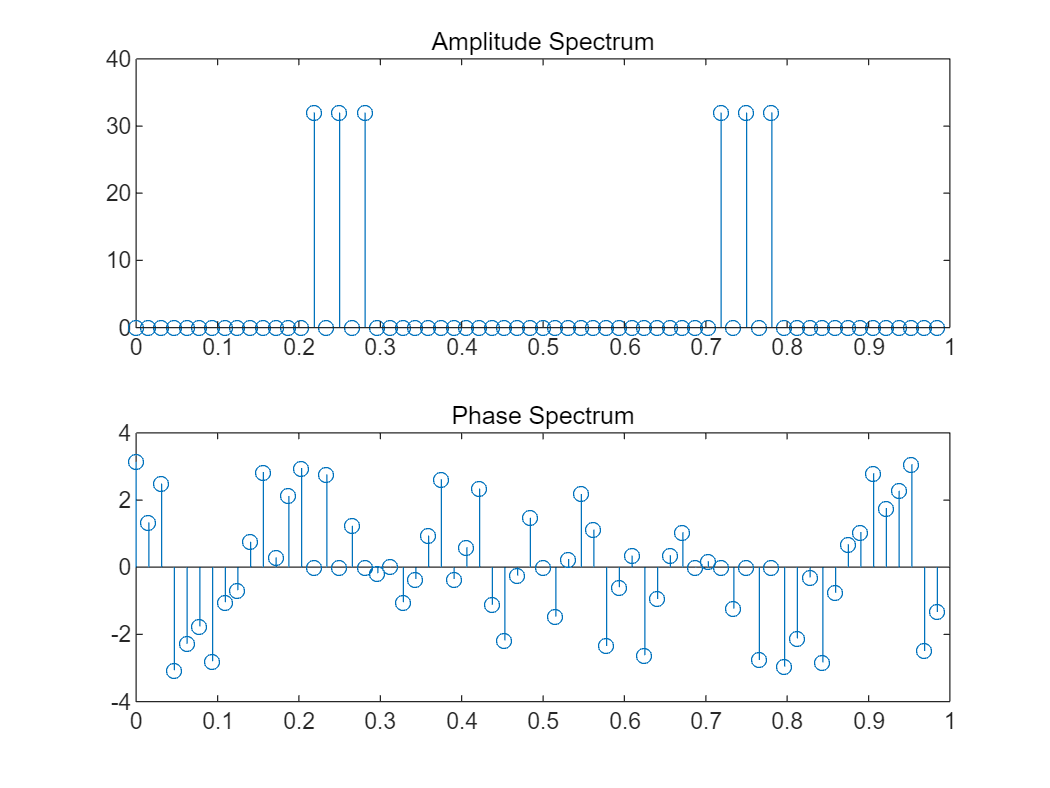

% LAB 2.2.4 刘兴琰 AI1 202264690069
frequencies = [7*pi/16, 9*pi/16, pi/2];
N = 64; 
k = 0:N-1;
x_k = cos(frequencies(1)*k) + cos(frequencies(2)*k) + cos(frequencies(3)*k);
X_k = fft(x_k);
magnitude_spectrum = abs(X_k);
phase_spectrum = angle(X_k);
frequency_bins = (0:N-1) / N;
subplot(2,1,1);
stem(frequency_bins, magnitude_spectrum);
title('Amplitude Spectrum');

subplot(2,1,2);
stem(frequency_bins, phase_spectrum);
title('Phase Spectrum');